# Initialize

figure;
img_path = "images/extra/week_1/";
imgs = Read_Images(img_path, "minecraft_block.jpg");

Reading images at - images\extra\week_1\minecraft_block.jpg
Number of images found in directory: 1
Read 1/1


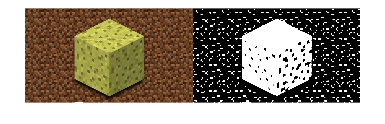

img = imgs{1};
bw_img = imbinarize(rgb2gray(img));
imshowpair(img, bw_img, 'montage');

### Morphology Init

strel_shape = 'square';

#### Line

line_length = 5;
line_degree = 90;
% increment values
len_inc = 5;
deg_inc = 25;
% choose what to increment to test its effects
line_test = 'degree';

#### Disk

n = 0;

#### Rectangle

m_rows = 3;
n_cols = 5;
% increment values
m_rows_inc = 10;
n_cols_inc = 10;
% choose what to increment to test its effects
rec_test = 'rows';

#### Square/Cube

width = 5;
% increment values
width_inc = 12;

#### Other

radius = 8;
oct_radius = 6; % octagon radius must by a positive multiple of 3
% increment values
r_inc = 5;

## Task 1: Erosion

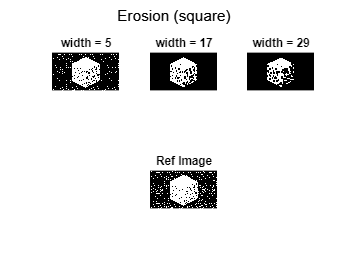

figure;

j = 1; rows = 2; cols = 3;
for i=2:4
    switch strel_shape
        case 'line'
            se_shape = strel(strel_shape, line_length, line_degree);
            title_temp = "len = " + line_length + " | deg = " + line_degree;
            if (strcmp(line_test, 'length'))
                line_length = line_length + len_inc;
            elseif (strcmp(line_test, 'degree'))
                line_degree = line_degree + deg_inc;
            end
        case 'disk'
            se_shape = strel(strel_shape, radius, n);
            title_temp = "radius = " + radius + " | n = " + n;
            n = 2^i;
        case 'diamond'
            se_shape = strel(strel_shape, radius);
            title_temp = "radius = " + radius;
            radius = radius + r_inc;
        case 'octagon'
            se_shape = strel(strel_shape, oct_radius);
            title_temp = "radius = " + oct_radius;
            oct_radius = oct_radius*3;
        case 'rectangle'
            se_shape = strel(strel_shape, [m_rows n_cols]);
            title_temp = "rows = " + m_rows + " | cols = " + n_cols;
            if (strcmp(rec_test, 'rows'))
                m_rows = m_rows + m_rows_inc;
            elseif (strcmp(rec_test, 'cols'))
                n_cols = n_cols + n_cols_inc;
            end
        case 'square'
            se_shape = strel(strel_shape, width);
            title_temp = "width = " + width;
            width = width + width_inc;
    end
    
    eroded_img = imerode(bw_img, se_shape);
    subplot(rows, cols, j); imshow(eroded_img);
    title(title_temp);
    j = j + 1;
end

% Reference image
subplot(rows, cols, 5); imshow(bw_img); title("Ref Image");
sgtitle("Erosion (" + strel_shape + ")");

### Conclusion

When **eroding** a binary image with a** black background**, the foreground gets eroded/removed, causing the **object to get smaller**.

## Task 1: Dilation

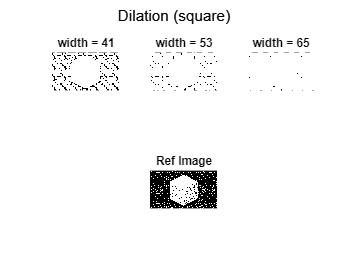

figure;

j = 1; rows = 2; cols = 3;
for i=2:4
    switch strel_shape
        case 'line'
            se_shape = strel(strel_shape, line_length, line_degree);
            title_temp = "len = " + line_length + " | deg = " + line_degree;
            if (strcmp(line_test, 'length'))
                line_length = line_length + len_inc;
            elseif (strcmp(line_test, 'degree'))
                line_degree = line_degree + deg_inc;
            end
        case 'disk'
            se_shape = strel(strel_shape, radius, n);
            title_temp = "radius = " + radius + " | n = " + n;
            n = 2^i;
        case 'diamond'
            se_shape = strel(strel_shape, radius);
            title_temp = "radius = " + radius;
            radius = radius + r_inc;
        case 'octagon'
            se_shape = strel(strel_shape, oct_radius);
            title_temp = "radius = " + oct_radius;
            oct_radius = oct_radius*3;
        case 'rectangle'
            se_shape = strel(strel_shape, [m_rows n_cols]);
            title_temp = "rows = " + m_rows + " | cols = " + n_cols;
            if (strcmp(rec_test, 'rows'))
                m_rows = m_rows + m_rows_inc;
            elseif (strcmp(rec_test, 'cols'))
                n_cols = n_cols + n_cols_inc;
            end
        case 'square'
            se_shape = strel(strel_shape, width);
            title_temp = "width = " + width;
            width = width + width_inc;
    end

    dilated_img = imdilate(bw_img, se_shape);
    subplot(rows, cols, j); imshow(dilated_img);
    title(title_temp);
    j = j + 1;
end

% Reference image
subplot(rows, cols, 5); imshow(bw_img); title("Ref Image");
sgtitle("Dilation (" + strel_shape + ")");

### Conclusion

When **dilating** a binary image with a **black background**, the white foreground expands which makes the 'white' **object to get bigger**.

## Task 1: Opening + Closing

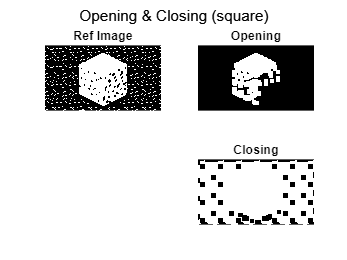

figure;
opened_img = imopen(bw_img, se_shape);
closed_img = imclose(bw_img, se_shape);

subplot(2, 2, 1); imshow(bw_img); title("Ref Image");
subplot(2, 2, 2); imshow(opened_img); title("Opening");
subplot(2, 2, 4); imshow(closed_img); title("Closing");
sgtitle("Opening & Closing (" + strel_shape + ")");

### Conclusion

When **opening** an image, the isolated pixels are eliminated, while **closing** an image eliminated the cracks and holes in the image.

## Task 1: Skeletonization

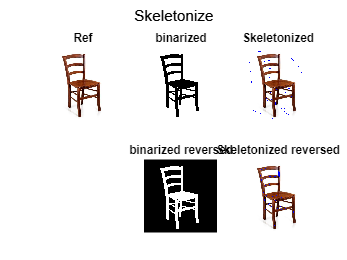

figure;

% Read better fitted image
img_skel = imread("images/chair.jpg");
bw_img_skel = imbinarize(rgb2gray(img_skel));
bw_img_skel_rev = imcomplement(bw_img_skel);

skeletonized_img = bwskel(bw_img_skel);
skeletonized_img_rev = bwskel(bw_img_skel_rev);

subplot(2,3,1); imshow(img_skel); title("Ref");
subplot(2,3,2); imshow(bw_img_skel); title("binarized");
subplot(2,3,3);
imshow(labeloverlay(img_skel, skeletonized_img,'Transparency',0));
title("Skeletonized");

subplot(2,3,5); imshow(bw_img_skel_rev); title("binarized reversed");
subplot(2,3,6);
imshow(labeloverlay(img_skel, skeletonized_img_rev,'Transparency',0));
title("Skeletonized reversed");

sgtitle("Skeletonize");

### Conclusion

When the image is binarized with a **white background**, the skeleton is formed **around the foreground object**.

However, with a **black background**, the **foreground object's skeleton** is extracted.

## Task 1: Edge Extraction

Based on the effects of the erosion and dilation, as one decreases the size of the foreground object and one increases the size respectively, we should be able to get the object's edges by substracting the dilated/eroded object with the original image.

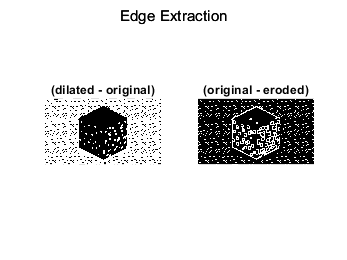

figure;
edges_dil = dilated_img - bw_img;
edges_erod = bw_img - eroded_img;

%imshowpair(edges_dil, edges_erod, 'montage');
subplot(1,2,1); imshow(edges_dil); title("(dilated - original)");
subplot(1,2,2); imshow(edges_erod); title("(original - eroded)");
sgtitle("Edge Extraction");

### Boundaries

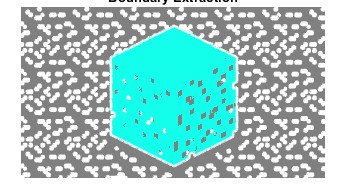

figure;
%[B,L,N,A] = bwboundaries(bw_img);

[B,L] = bwboundaries(bw_img,'noholes');
imshow(label2rgb(L, @jet, [.5 .5 .5]))
hold on

for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end
title("Boundary Extraction");
sgtitle("");

## Task 1: Questions

Determine which of the above operations is suitable for each goal.

**Fill narrow channels, preserving size and shape of larger objects**

- bwfill

**Remove small objects, preserving size and shape of larger objects**

- bwareaopen

**Remove small objects**

- imerode

**Make objects more visible**

- imdilate

## Task 2: Other Morph Operators

I will need to use other morph operators in order to **remove small objects** from the image, **fill holes** in the main object to clearly **segment** it from the background.

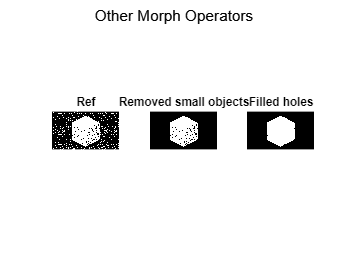

figure;
bw_img_areaopen = bwareaopen(bw_img, 1000);
bw_img_filled = bwfill(bw_img_areaopen, 'holes');

subplot(1, 3, 1); imshow(bw_img); title("Ref");
subplot(1, 3, 2); imshow(bw_img_areaopen); title("Removed small objects");
subplot(1, 3, 3); imshow(bw_img_filled); title("Filled holes");
sgtitle("Other Morph Operators");

## Task 3: Image Segmenter App

Used Matlab's Image Segmenter app to try some other segmentation techniques and export them into functions.

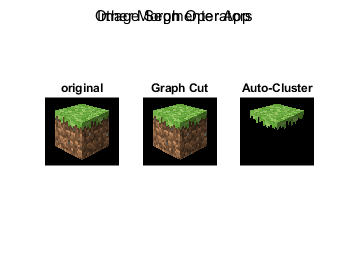

figure;

img_minecraftblock = imread(img_path + "minecraft_block.png");
%img_minecraftblocks = imread(img_path + "minecraft_blocks.jpg");

% First use operations on original image that was used to create them
[BW_gc, img_graphcut] = segmentImage_graphcut(img_minecraftblock);
[BW_ac, img_autocluster]= segmentImage_autocluster(img_minecraftblock);

% Plot
subplot(1,3,1); imshow(img_minecraftblock); title("original");
subplot(1,3,2); imshow(img_graphcut_1); title("Graph Cut");
subplot(1,3,3); imshow(img_autocluster_1); title("Auto-Cluster");
sgtitle("Image Segmenter App");